
clear all; close all; clc;
alpha = 0.01; % set significance level


%% get data
real=csvread("impianti/workload_characterization/data/ll_pca_clustering_subset.csv",1); %workload reale
syntetic=csvread("impianti/workload_characterization/data/ll_syntetic_pca_clustering_subset.csv",1); %workload sintetico

%real

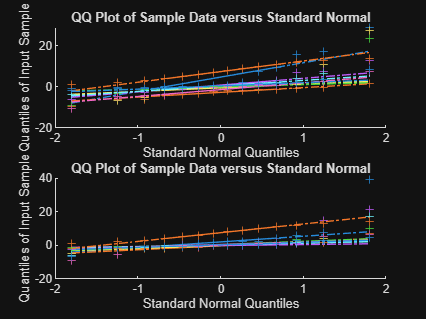

%% normal distribution visual test
figure();
subplot(2,1,1);
qqplot(real);
subplot(2,1,2);
qqplot(syntetic);

%% normal distribution Kolmogorov-Smirnov test
[h_normal_real,p_normal_real] = kstest(real, "Alpha", alpha);
[h_normal_sint,p_normal_sint] = kstest(syntetic, "Alpha", alpha);

fprintf('Kolmogorov-Smirnov test results:');

Kolmogorov-Smirnov test results:

fprintf('- real workload null hypotesis: %d', h_normal_real);

- real workload null hypotesis: 1

fprintf('- syntetic workload null hypotesis: %d', h_normal_sint);

- syntetic workload null hypotesis: 1

%% Wilcoxon rank-sum non-parametric unpaired hypotesis test 

N=size(real,2); % column size
p_wilc = zeros(1,N);
h_wilc = zeros(1,N);

for i= 1:N
    [p_wilc(i), h_wilc(i)] = ranksum(syntetic(:,i), real(:,i),"alpha",alpha);
end

h_wilc

h_wilc =      0     0     0     0     0     0     0     0     0


p_wilc

p_wilc =     0.9085    0.0108    0.7304    0.9451    0.9085    0.9817    0.7304    0.6295    1.0000
